# **Tutorial - 1: Modeling a Permanent Magnet in FEMM**

ELL851 - Computer Aided Design of Electrical Machines

**Problem Description: **

A permanent magnet of a certain grade (N42) is modeled in FEMM, and its fields and magnitude are plotted. Dimensions and magnetization are specified below.

What'll you understand: *Assigning materials (magnet, air), magnetization assignment*

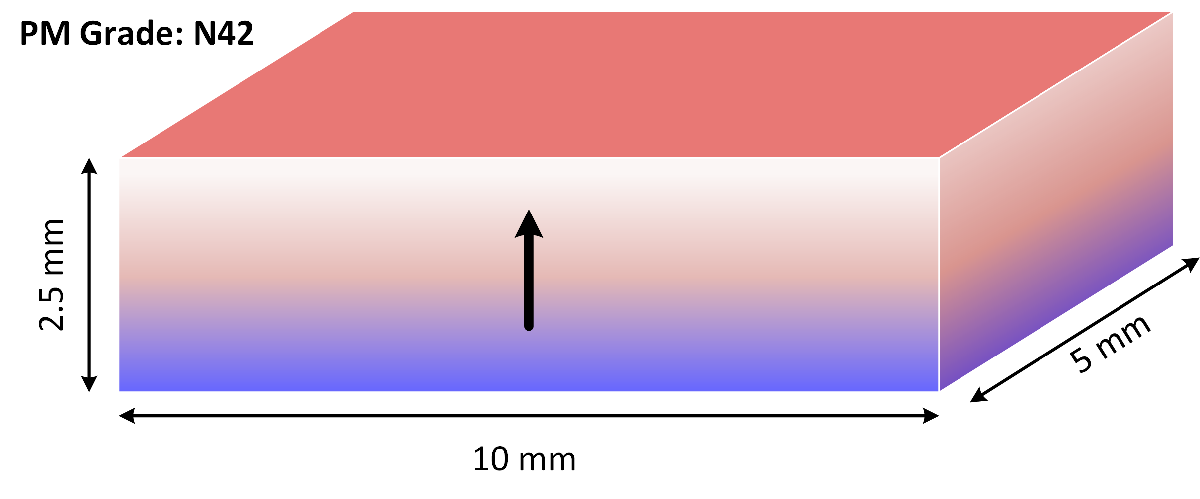

## Define Initial Design Parameters (Known)

clc; clear all;
freq  = 0; %frequency of the problem
% Magnet dimensions
MagW = 10; % Magnet Width, units: mm
MagH = 2.5; % Magnet Height
MagD = 10; % Magnet Depth

% Boundary Properties
boundary_rad = 20; % boundary radius, 20 mm

## Open FEMM and Define Initial Settings

openfemm();
newdocument(0); % for Magnetostatic problems
messagebox('Tutorial-I, Permanent Magnet'); %display name of tutorial
mi_probdef(0,'millimeters','planar',1.e-8,5,30); %problem definition

## Geometry Definition

mi_drawrectangle ([-MagW/2 0; MagW/2 MagH])
mi_drawarc(boundary_rad, MagH/2, -boundary_rad, MagH/2, 180, 5) %boundary arc 1
mi_drawarc(-boundary_rad, MagH/2, boundary_rad, MagH/2, 180, 5) %boundary arc 2
mi_zoomnatural

## Boundary Assignment

mi_addboundprop('Air',0,0,0,0,0,0,0,0,0)
mi_selectarcsegment(0,boundary_rad); mi_selectarcsegment(0,-boundary_rad); 
%Select the outer boundary
mi_setarcsegmentprop(5, 'Air', 0, 1); %group 1
mi_clearselected

## Material Assignment

% Get materials
mi_getmaterial('Air');
mi_getmaterial('N42');

% Set materials to labels
mi_addblocklabel(0,boundary_rad/2); mi_selectlabel(0,boundary_rad/2);
mi_setblockprop('Air',1,0,'None',0,3,0); %Air, group 3
mi_clearselected();

mi_addblocklabel(0,MagH/2); mi_selectlabel(0,MagH/2);
mi_setblockprop('N42',1,0,'None',90,2,0); %N42, group 2
mi_clearselected();

## Analysis and Solution

%Save before analyzing
mi_saveas('Assignment1.FEM');
mi_createmesh; mi_analyze;
mi_loadsolution; mi_zoomnatural;

mo_showdensityplot(1,0,1,0.0,'bmag'); 
%outputs flux density in 
mo_setgrid(0.5, 'cart');

# **Assignment 1 - Questions:**

- Model the above permanent magnet with dimensions: **10mm x 2.5mm x 10mm and magnetization vector = 0deg (right)** using FEMM and MATLAB. Only '.mlx' files accepted.

- What does the material grade 'N42' nomenclature signify?

- List the names of different grades of similar PMs.

- What is the thermal limit for demagnetization in this particular grade of magnet?

- Plot the variation of flux density along the x and y axes at 0.1 mm gap from the surface of the PM in the below window.

## Post Processing

Plot the flux density along x and y axis at 0.1 mm air-gap from PM

% Insert solution here